% 1.0版本
% 单个被试、单个通道的时频变换结果的汇总
clear;clc;close all;

filename = 'D:\Matlab_data_file\EEGdata\data_for_TFA\sub1.set';
EEG = pop_loadset(filename);

pop_loadset(): loading file D:\Matlab_data_file\EEGdata\data_for_TFA\sub1.set ...



% EEG：channel*time*epoch
% 提取某个通道的数据
x = squeeze(EEG.data(29,:,:));

% 把epoch的时间单位矫正为秒
xtimes = EEG.times/1000;

% 时频结果的时间分辨率
t = EEG.times/1000;

% 时频结果的频域分辨率(1~40HZ)的频率都要计算
f = 1:40;

% 采样率
fs = EEG.srate;

%窗长（单位：秒）
winsize = 0.2;

% 时频转换（短时傅里叶变换）
% S: 复数形式的数据
% P: 不含有相位的幅值（单位uv平方）fre*timepoint*epoch
% F: 相位谱信息
% U: 用于求真实幅度的变量
[~,P,~,~] = sub_stft(x,xtimes,t,f,fs,winsize);


Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!


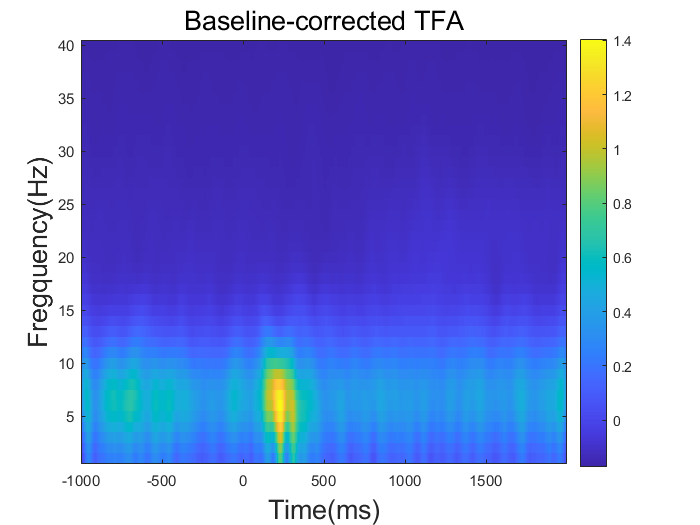


% 得到的结果求epoch平均值，p_data: frequency*channel
p_data = squeeze(mean(P,3));

% 基线矫正（为了凸显ERD和ERS）
% 选择基线范围，刺激前0.8到前0.2秒
% 之所以选留下最开始的0.2和最后0.2是因为这个区间的数据因为加窗补零是不准确的
t_pre_idx = (t>=-0.8)&(t<=-0.2);

% 预分配一个数组储存能量数据
p_bc = zeros(size(p_data,1),size(p_data,2));

% 对于每个频率点
for i = 1:size(p_data,1)
    % 提取该频率点所有时刻的能量值
    temp = squeeze(p_data(i,:));
    %（低频用减法）该频率点所有时刻的能量值，减去基线时间段的平均能量值
    p_bc(i,:) = temp - mean(p_data(t_pre_idx));
    % （高频-beta以及以上用除法）
    % p_bc(i,:) = temp/mean(p_data(t_pre_idx));
    % p_bc: 进行基线矫正后的能量值数据：fre*channel
end

% 绘图
figure;
% 时频图
imagesc(t*1000,f,p_bc);
% 调整xy轴正方向
axis xy;
% 显示颜色条图例
colorbar;
% 限制colorbar的数值范围
caxis = ([-1,3]);
% 各种文字说明
ylabel('Fregquency(Hz)',"FontSize",16);
xlabel('Time(ms)',"FontSize",16);
title('Baseline-corrected TFA',"FontSize",16);

% 2.0版本
% 单个被试多个通道的时频信号汇总
clear;clc;

filename = 'D:\Matlab_data_file\EEGdata\data_for_TFA\sub1.set';
EEG = pop_loadset(filename);

pop_loadset(): loading file D:\Matlab_data_file\EEGdata\data_for_TFA\sub1.set ...



% 把epoch的时间单位矫正为秒
xtimes = EEG.times/1000;
% 时频结果的时间分辨率
t = EEG.times/1000;
% 时频结果的频域分辨率(1~40HZ)的频率都要计算
f = 1:40;
% 采样率
fs = EEG.srate;
%窗长（单位：秒）
winsize = 0.2;

% 内存预分配
p_data = zeros(60,40,1500);
p_bc = zeros(60,40,1500);

% EEG：channel*time*epoch
% 对于通道i：
for i = 1:size(EEG.data,1)
    % 提取该通道time*epoch数据，进行短时傅里叶变换
    x = squeeze(EEG.data(i,:,:));
    [~,P,~,~] = sub_stft(x,xtimes,t,f,fs,winsize);
    % P:fre*time*epoch，求epoch均值
    % p_data: chan*fre*time
    p_data(i,:,:) = squeeze(mean(P,3));
end


Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 1

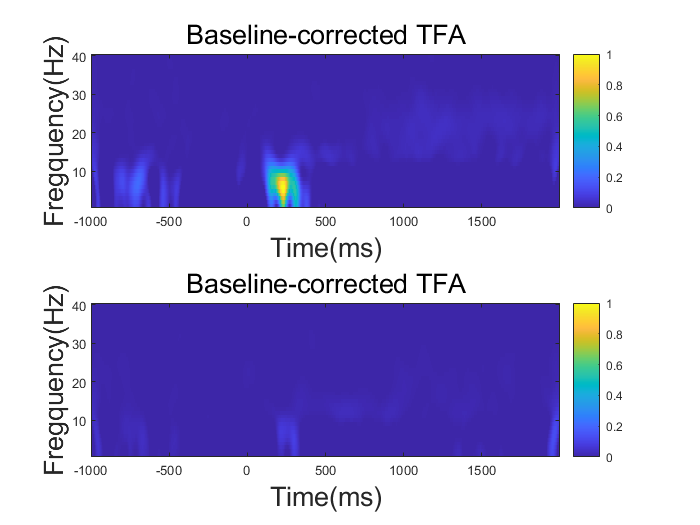


    % 基线矫正（为了凸显ERD和ERS）
    % 选择基线范围，刺激前0.8到前0.2秒
    % 之所以选留下最开始的0.2和最后0.2是因为这个区间的数据因为加窗补零是不准确的
    t_pre_idx = (t>=-0.8)&(t<=-0.2);
    % 预分配一个数组储存能量数据
    p_bc = zeros(size(p_data,1),size(p_data,2),size(p_data,3));
    % 对于第i个通道
for i = 1:size(p_data,1)
    % 第i个通道上的第j个频率点：
    for j = 1:size(p_data,2)
        temp = squeeze(p_data(i,j,:));
        %（低频用减法）该频率点所有时刻的能量值，减去基线时间段的平均能量值
        % i通道，j频率上所有时间点的能量：
        p_bc(i,j,:) = temp - mean(temp(t_pre_idx));
        % p_bc: 进行基线矫正后的能量值数据：chan*fre*time
        % （高频-beta以及以上用除法）
        % p_bc(i,:) = temp/mean(p_data(t_pre_idx));
    end
end

% 绘图
figure;
subplot(211);
% 时频图（顶叶-Cz）
imagesc(t*1000,f,squeeze(p_bc(28,:,:)),[0,1]);
% 调整xy轴正方向
axis xy;
% 显示颜色条图例
colorbar;
% 各种文字说明
ylabel('Fregquency(Hz)',"FontSize",16);
xlabel('Time(ms)',"FontSize",16);
title('Baseline-corrected TFA',"FontSize",16);

subplot(212);
% 时频图（左侧颞叶）
imagesc(t*1000,f,squeeze(p_bc(24,:,:)),[0,1]);
% 调整xy轴正方向
axis xy;
% 显示颜色条图例
colorbar;
% 各种文字说明
ylabel('Fregquency(Hz)',"FontSize",16);
xlabel('Time(ms)',"FontSize",16);
title('Baseline-corrected TFA',"FontSize",16);

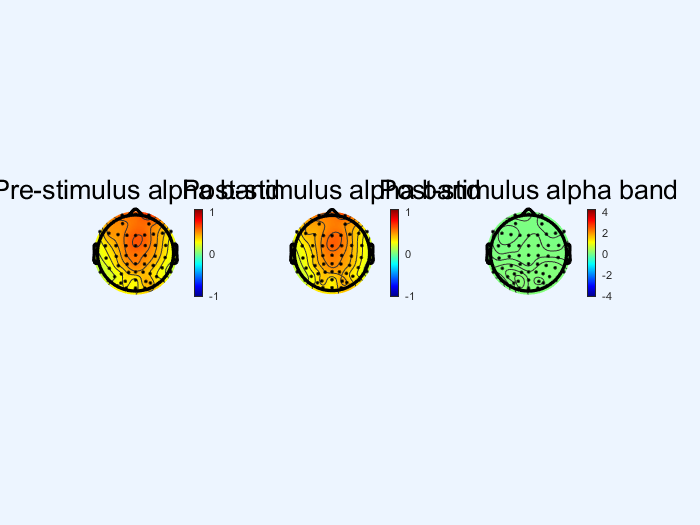


% 能量地形图
% 前0.8秒到前0.2秒的alpha波
roi1_t = [-0.8,-0.2];
roi1_f = [8 13];
t_idx = (t>=roi1_t(1))&(t<roi1_t(2));
f_idx = (f>=roi1_f(1))&(f<roi1_f(2));
pre_alpha = squeeze(mean(mean(p_bc(:,f_idx,t_idx),2),3));

% 0.2秒到1.5秒的alpha波
roi1_t = [0.2,1.5];
roi1_f = [8 13];
t_idx = (t>=roi1_t(1))&(t<roi1_t(2));
f_idx = (f>=roi1_f(1))&(f<roi1_f(2));
post_alpha = squeeze(mean(mean(p_bc(:,f_idx,t_idx),2),3));

figure;
% 刺激前
subplot(1,3,1);
topoplot(pre_alpha,EEG.chanlocs,'maplimits',[-1,1]);
title('Pre-stimulus alpha band','FontSize',16);
colorbar;
% 刺激后
subplot(1,3,2);
topoplot(post_alpha,EEG.chanlocs,'maplimits',[-1,1]);
title('Post-stimulus alpha band','FontSize',16);
colorbar;
% 刺激后-刺激前
subplot(1,3,3);
topoplot(post_alpha - pre_alpha,EEG.chanlocs,'maplimits',[-4,4]);
title('Post-stimulus alpha band','FontSize',16);
colorbar;

% 3.0版本
% 多个被试多个通道的时频信号汇总

clear;clc;close all;

% 数据路径
data_path = ['D:\Matlab_data_file\EEGdata\data_for_TFA',filesep];

% 预先设置的变量（在循环体中保持不变，因此可以放在循环体外）
% 时频图中的y轴数组（频率）
f = 1:40;
% 窗长
winsize = 0.2;
% 最大被试id
sub_max = 4;

% 对于被试i
for i = 1:sub_max
    try
        % 导入该被试数据
        EEG = pop_loadset([data_path,'sub',num2str(i),'.set']);
        % 将时间点单位矫正为秒
        xtimes = EEG.times/1000;
        % 时频图的x轴数组（同样也是短时傅里叶变换的必要参数）
        t = EEG.times/1000;
        % 采样率
        fs = EEG.srate;
        
        % 对于通道j
        for j = 1:EEG.nbchan
            % EEG.data: chen*time*epoch
            % 提取这个通道的所有epoch数据
            x = squeeze(EEG.data(j,:,:));
            % x: time*epoch
            % 短时傅里叶变换
            [~,P,~,~] = sub_stft(x,xtimes,t,f,fs,winsize);
            % P：fre*time*epoch
            % 汇总：第i个被试j通道上所有能量频段所有时间点的epoch平均值
            p_data(i,j,:,:) = squeeze(mean(P,3));
            % p_data: sub*chan*fre*time
        end 
    catch ME
    end
end

pop_loadset(): loading file D:\Matlab_data_file\EEGdata\data_for_TFA\sub1.set ...



Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 1

pop_loadset(): loading file D:\Matlab_data_file\EEGdata\data_for_TFA\sub2.set ...



Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 1

pop_loadset(): loading file D:\Matlab_data_file\EEGdata\data_for_TFA\sub3.set ...



Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 1

pop_loadset(): loading file D:\Matlab_data_file\EEGdata\data_for_TFA\sub4.set ...



Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 100%  Done!
Done!

Short-time Fourier Transform: 1500 Time Points x 40 Frequency Bins x 216 Trials
Processing... 1

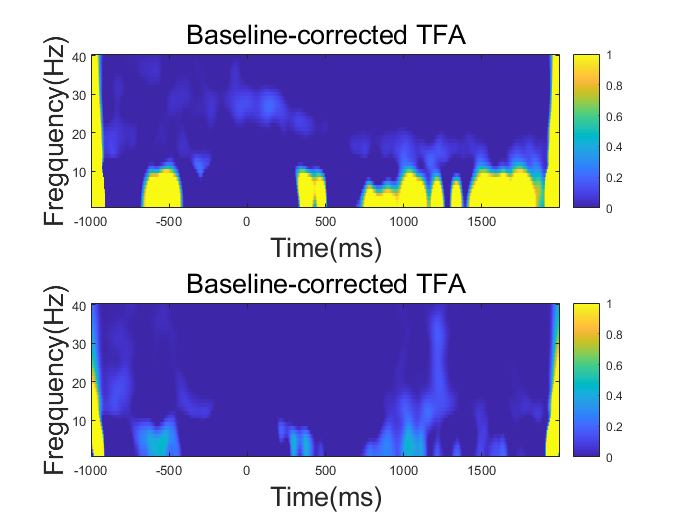


% 对p_data数据进行基线矫正
% 基线索引
t_pre_idx = (t>=-0.8)&(t<=-0.2);

% 对于被试i：
for i = 1:size(p_data,1)
    % 对于通道j
    for j = 1:size(p_data,2)
        % 对于第k个频率点上的所有时间点能量值
        for k = 1:size(p_data,3)
            temp = squeeze(p_data(i,j,k,:));
            % temp: time，一维数组
            % 低频用减法，高频用除法
            p_bc(i,j,k,:) = temp - mean(temp(t_pre_idx));
            % p_bc(i,j,k,:) = temp/mean(temp(t_pre_idx));
            % p_bc: sub*chan*fre(rebased)*time
        end     
    end  
end

% 绘图（特定通道的组平均时频图）
figure;
subplot(211);
% 时频图（Fpz）
imagesc(t*1000,f,squeeze(mean(p_bc(:,2,:,:),1)),[0,1]);
% 调整xy轴正方向
axis xy;
% 显示颜色条图例
colorbar;
% 各种文字说明
ylabel('Fregquency(Hz)',"FontSize",16);
xlabel('Time(ms)',"FontSize",16);
title('Baseline-corrected TFA',"FontSize",16);

subplot(212);
% 时频图（Fz）
imagesc(t*1000,f,squeeze(mean(p_bc(:,10,:,:),1)),[0,1]);
% 调整xy轴正方向
axis xy;
% 显示颜色条图例
colorbar;
% 限制colorbar的数值范围
caxis = ([-3,3]);
% 各种文字说明
ylabel('Fregquency(Hz)',"FontSize",16);
xlabel('Time(ms)',"FontSize",16);
title('Baseline-corrected TFA',"FontSize",16);

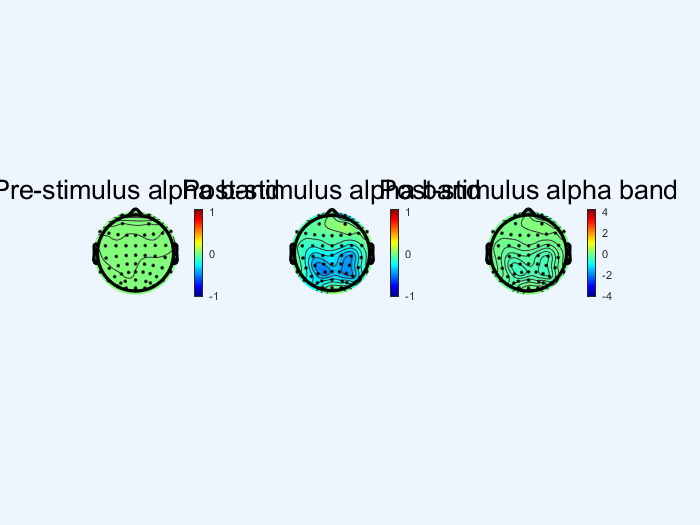


% 特定通道，特定时间的组平均能量地形图
% 前0.8秒到前0.2秒的alpha波
roi1_t = [-0.8,-0.2];
roi1_f = [8 13];
t_idx = (t>=roi1_t(1))&(t<roi1_t(2));
f_idx = (f>=roi1_f(1))&(f<roi1_f(2));
pre_alpha = squeeze(mean(mean(mean(p_bc(:,:,f_idx,t_idx),3),4),1));

% 0.2秒到1.5秒的alpha波
roi1_t = [0.2,1.5];
roi1_f = [8 13];
t_idx = (t>=roi1_t(1))&(t<roi1_t(2));
f_idx = (f>=roi1_f(1))&(f<roi1_f(2));
post_alpha = squeeze(mean(mean(mean(p_bc(:,:,f_idx,t_idx),3),4),1));

figure;
% 刺激前
subplot(1,3,1);
topoplot(pre_alpha,EEG.chanlocs,'maplimits',[-1,1]);
title('Pre-stimulus alpha band','FontSize',16);
colorbar;
% 刺激后
subplot(1,3,2);
topoplot(post_alpha,EEG.chanlocs,'maplimits',[-1,1]);
title('Post-stimulus alpha band','FontSize',16);
colorbar;
% 刺激后-刺激前
subplot(1,3,3);
topoplot(post_alpha - pre_alpha,EEG.chanlocs,'maplimits',[-4,4]);
title('Post-stimulus alpha band','FontSize',16);
colorbar;